# **FILTROS IRR**

## FILTRO BUTTERWORTH PASA BAJOS

clear 
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


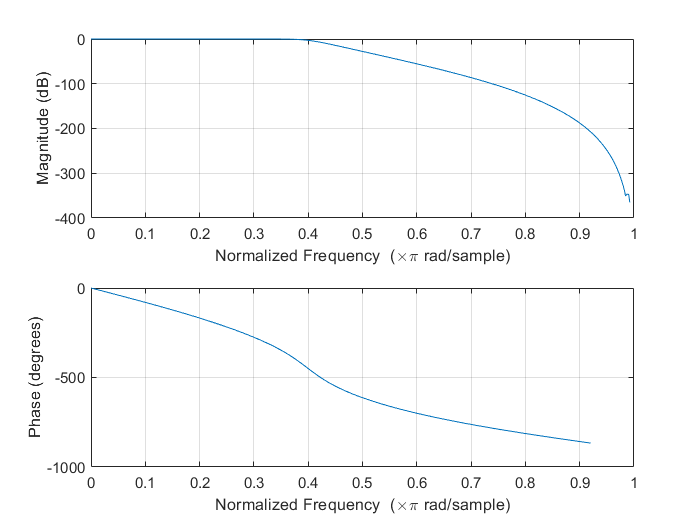


fc = 200; % FRECUENCIA DE CORTE
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = fc/(fs/2); % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 10; % ORDEN DEL FILTRO
[num, den] = butter(n, Wn, 'Low'); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

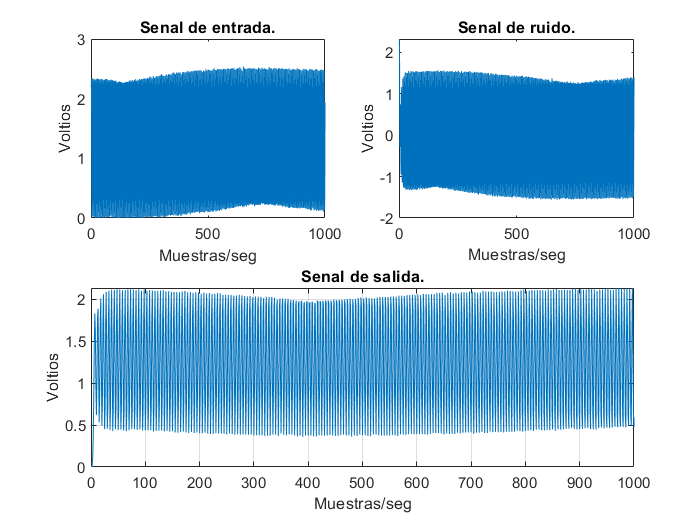

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido)
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

## FILTRO BUTTERWORTH PASA ALTOS

clear 
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


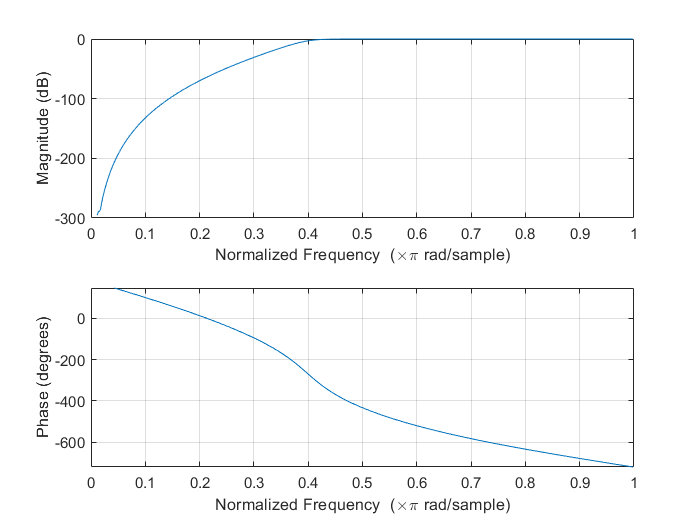


fc = 200; % FRECUENCIA DE CORTE
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = fc/(fs/2); % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 10; % ORDEN DEL FILTRO
[num, den] = butter(n, Wn, 'High'); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

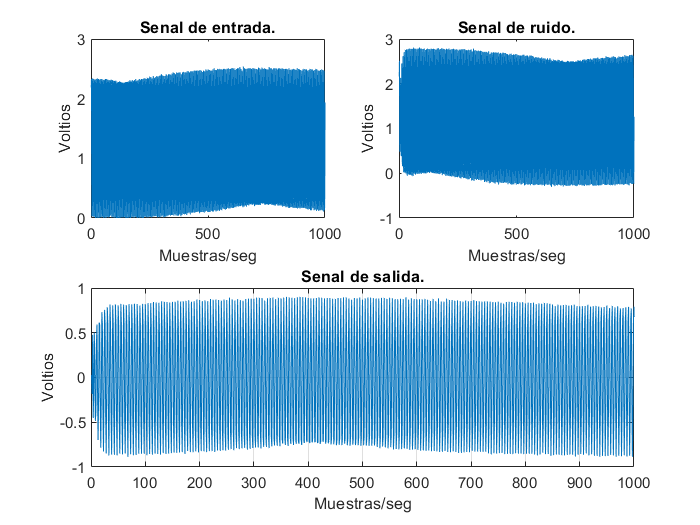

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido)
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

## FILTRO BUTTERWORTH PASA BANDA

clear 
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


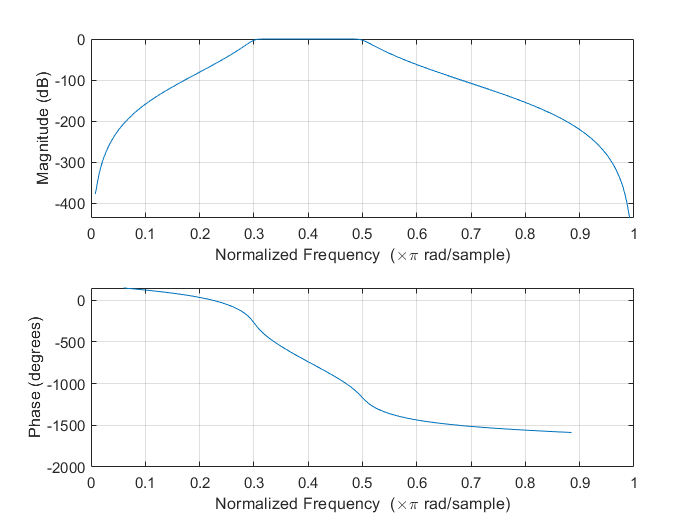


fc1 = 150; % FRECUENCIA DE CORTE INFERIOR
fc2 = 250; % FRECUENCIA DE CORTE SUPERIOR
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = [fc1/(fs/2) fc2/(fs/2)]; % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 10; % ORDEN DEL FILTRO
[num, den] = butter(n, Wn, 'Bandpass'); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

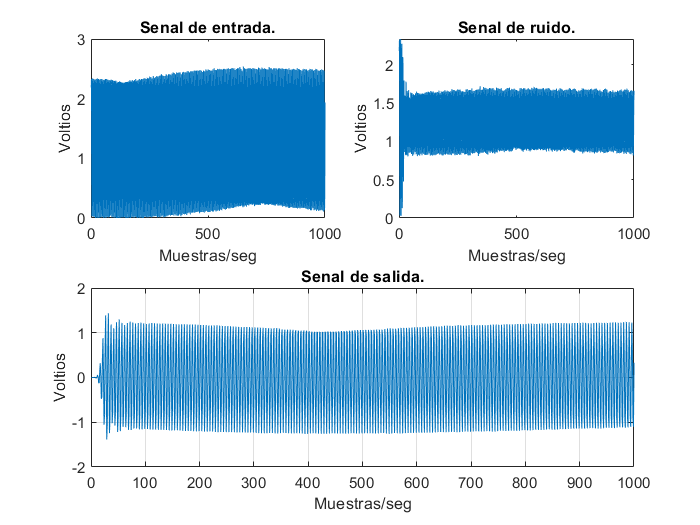

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido)
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

## FILTRO BUTTERWORTH RECHAZA BANDA

clear 
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


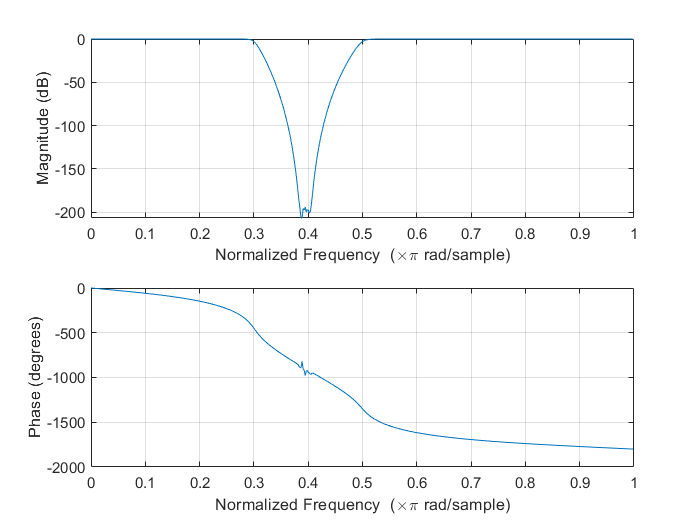


fc1 = 150; % FRECUENCIA DE CORTE INFERIOR
fc2 = 250; % FRECUENCIA DE CORTE SUPERIOR
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = [fc1/(fs/2) fc2/(fs/2)]; % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 10; % ORDEN DEL FILTRO
[num, den] = butter(n, Wn, 'Stop'); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

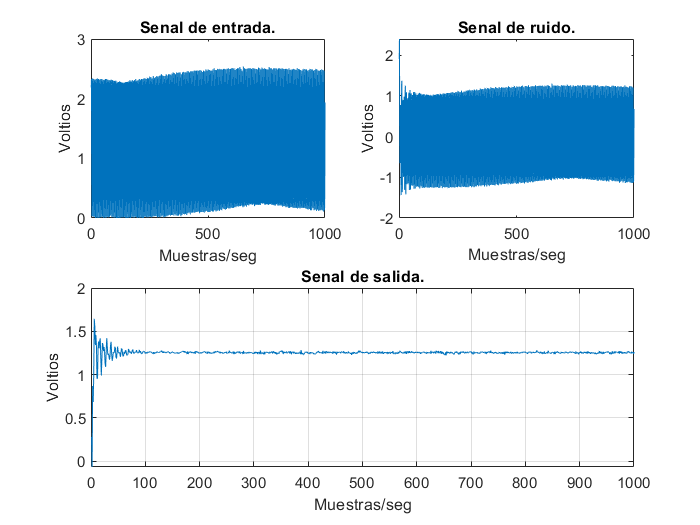

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido)
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

# **FILTROS FIR**

## FILTRO PARA MUESTREO EN FRECUENCIA PASA BAJOS

clear
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


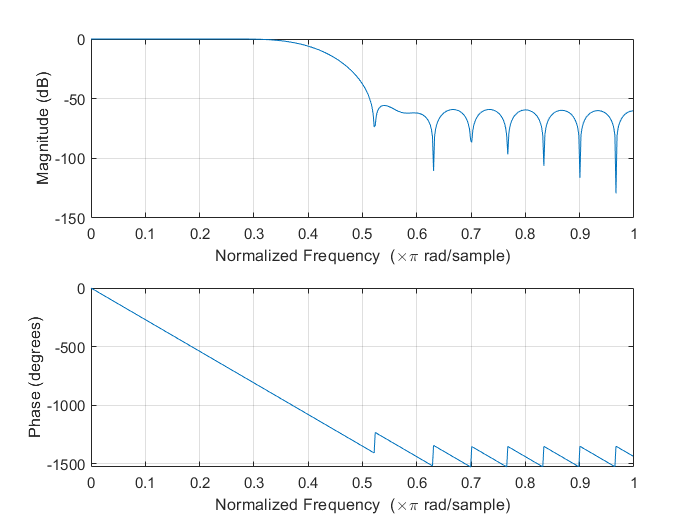


fc = 200; % FRECUENCIA DE CORTE
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = [0 fc/(fs/2) fc/(fs/2) 1]; % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 30; % ORDEN DEL FILTRO
m = [1 1 0 0]; % FRECUENCIAS DESEADAS
[num, den] = fir2(n, Wn, m); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

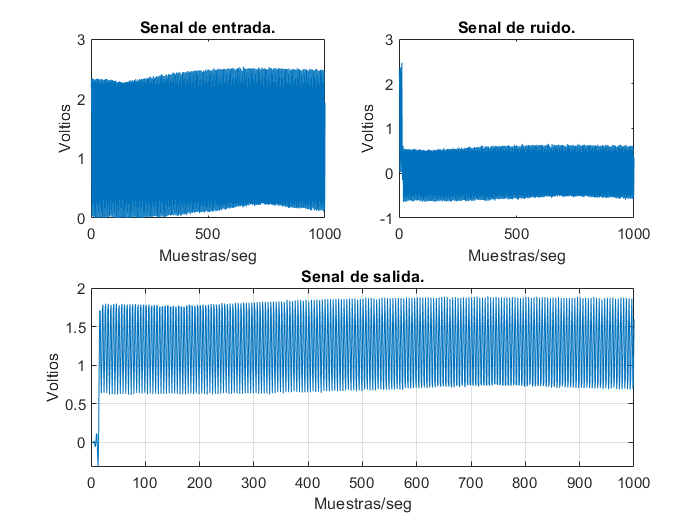

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido)
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

## FILTRO PARA MUESTREO EN FRECUENCIA PASA ALTOS

clear
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


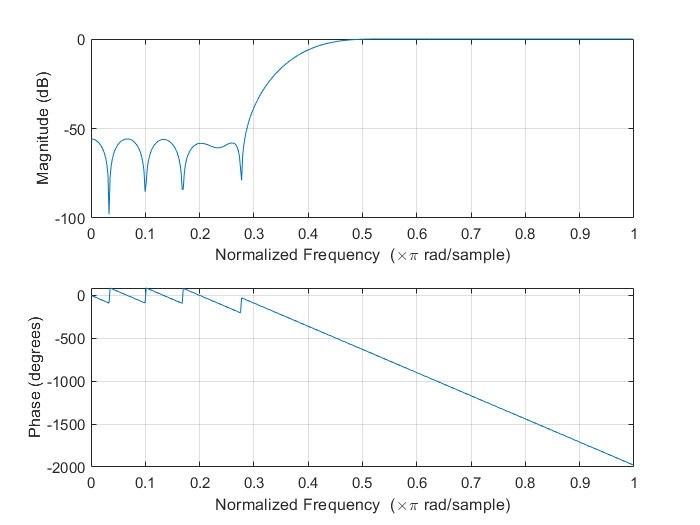


fc = 200; % FRECUENCIA DE CORTE
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = [0 fc/(fs/2) fc/(fs/2) 1]; % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 30; % ORDEN DEL FILTRO
m = [0 0 1 1]; % FRECUENCIAS DESEADAS
[num, den] = fir2(n, Wn, m); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

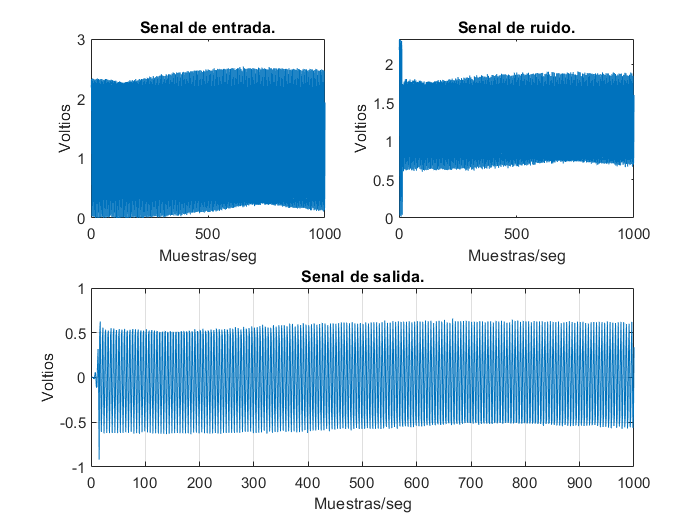

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido)
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

## FILTRO PARA MUESTREO EN FRECUENCIA PASA BANDA

clear
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


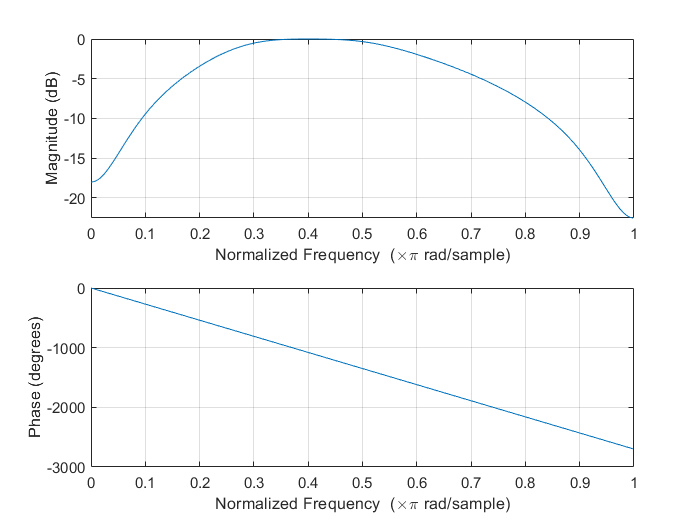


fc1 = 150; % FRECUENCIA DE CORTE INFERIOR
fc2 = 250; % FRECUENCIA DE CORTE SUPERIOR
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = [0 fc1/(fs/2) fc2/(fs/2) 1]; % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 30; % ORDEN DEL FILTRO
m = [0 1 1 0]; % FRECUENCIAS DESEADAS
[num, den] = fir2(n, Wn, m); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

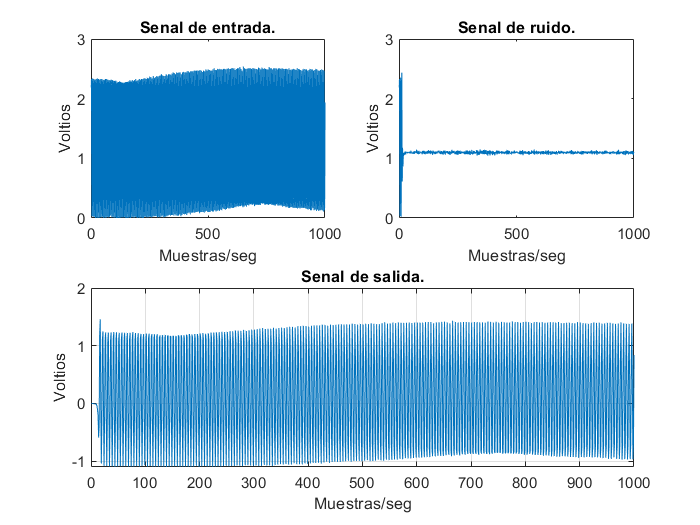

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido)
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

## FILTRO PARA MUESTREO EN FRECUENCIA RECHAZA BANDA

clear
clc

dataIn = load('200Hz6seg.txt') % SENAL DE ENTRADA

dataIn =     2.1800
    2.3300
    0.9900
    0.0300
    0.7400
    2.1800
    2.3400
    1.0000
    0.0200
    0.7600


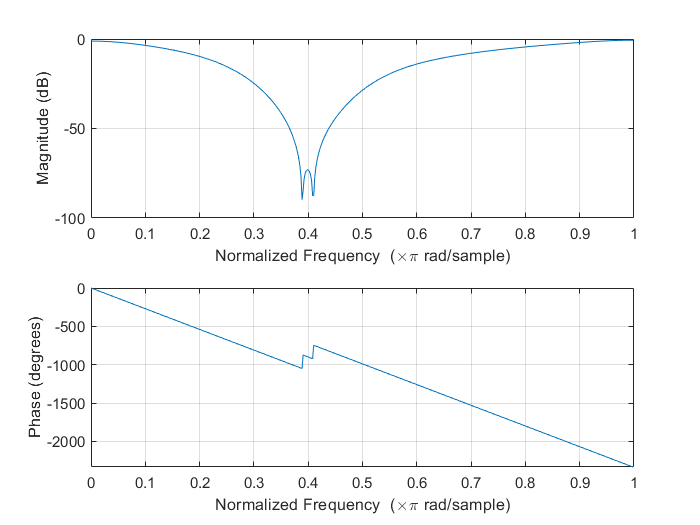


fc1 = 150; % FRECUENCIA DE CORTE INFERIOR
fc2 = 250; % FRECUENCIA DE CORTE SUPERIOR
fs = 1000; % FRECUENCIA DE MUESTREO
Wn = [0 fc1/(fs/2) fc2/(fs/2) 1]; % FRECUENCIA NORMALIZADA RAD/MUESTRA
n = 30; % ORDEN DEL FILTRO
m = [1 0 0 1]; % FRECUENCIAS DESEADAS
[num, den] = fir2(n, Wn, m); % FILTRO
freqz(num, den); % RESPUESTA DEL FILTRO

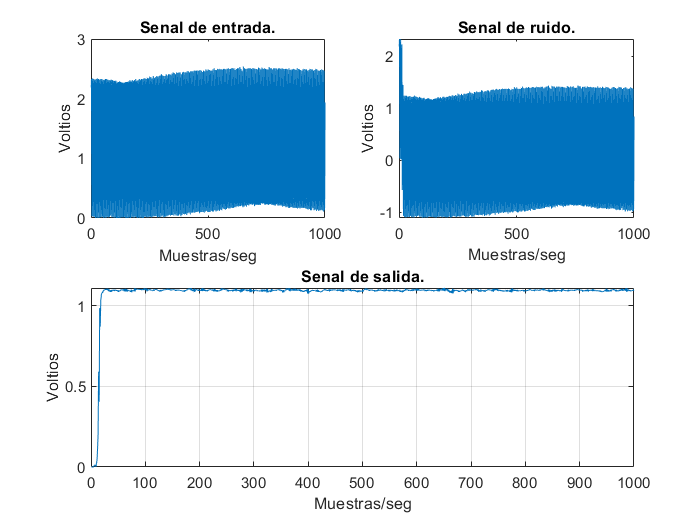

dataOut = filter(num, den,dataIn); % SENAL FILTRADA
dataRuido = dataIn - dataOut; % SENAL DE RUIDO

subplot(2, 2, 1)
plot(dataIn)
title('Senal de entrada.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, 2)
plot(dataRuido) 
title('Senal de ruido.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])

subplot(2, 2, [3, 4])
plot(dataOut)
title('Senal de salida.'); xlabel('Muestras/seg'); ylabel('Voltios')
xlim([0 1000])
grid on

# **FILTRO DE KALMAN**